d = audioread('recording.wav')

d =          0         0
         0         0
         0         0
         0         0
         0    0.3052
         0    0.3052
         0         0
         0         0
         0         0
         0    0.3052


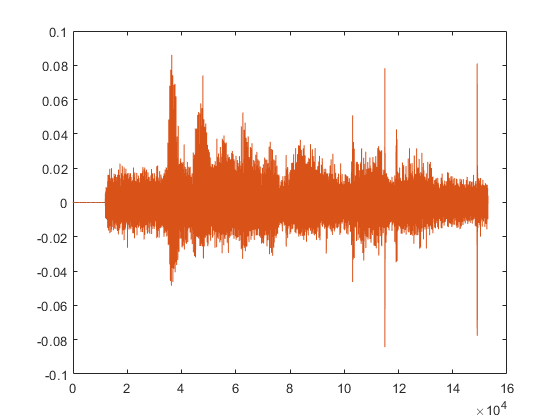

plot(d)


[d, Fs] = audioread('recording.wav'); % y is the audio data, Fs is the sampling rate
sound(d,Fs)
d2 = flipud(d)

d2 =     0.0021    0.0021
   -0.0061   -0.0061
   -0.0074   -0.0074
   -0.0000   -0.0000
    0.0041    0.0041
   -0.0008   -0.0007
   -0.0051   -0.0051
   -0.0030   -0.0030
    0.0013    0.0013
    0.0002    0.0002



%reverse
audiowrite('reverse_hello.mp4',d2,Fs)
d3 = audioread('reverse_hello.mp4')

d3 =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


[d3,Fs] = audioread('reverse_hello.mp4')

d3 =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs = 44100

%sound(d3,Fs)

%double
d4 = downsample(d,2)

d4 =          0         0
         0         0
         0    0.3052
         0         0
         0         0
         0         0
         0    0.3052
         0         0
         0         0
         0         0



b = ones(40,1)/40

b =     0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250
    0.0250


dlp = filter(b,1,d)

dlp =          0         0
         0         0
         0         0
         0         0
         0    0.0763
         0    0.1526
         0    0.1526
         0    0.1526
         0    0.1526
         0    0.2289


%sound(dlp,Fs)

%sound(d4,Fs)
%sound(d4,Fs/2)




